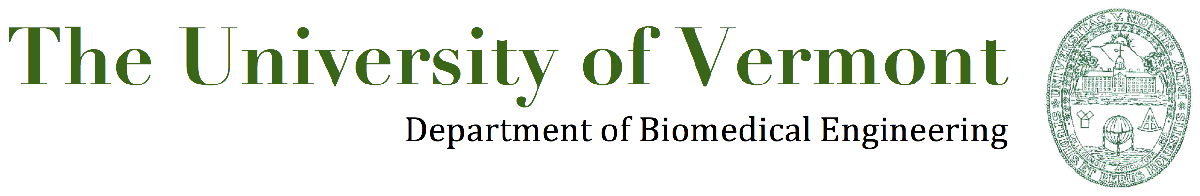

**Automated Cell Counting with Matlab**

Written by Ryan S. McGinnis - ryan.mcginnis@uvm.edu

Adapted from http://blog.pedro.si/2014/04/basic-cell-segmentation-in-matlab.html

**Background**

Talk with your lab partner about the following questions and make some notes in your lab document about what you discuss. You should have this discussion prior to completing the lab as outlined below.

1. Why might an investigator want to determine the total number of cells growing in a petri dish, in a flask, in a test tube, or on a slide?

2. How could you estimate the number of cells in a Petri dish? What are some limitations of your proposed method?

**Basic Image Manipulation **

*Load original stained cell image*

A = imread('cells.png');
imshow(A);

*3. What is the shape of A? What is the range of values it contains?*

*Convert the image to grayscale*

I = rgb2gray(A);
imshow(I);

*4. What is the shape of I? What is the range of values it contains?*

*Peform some contrast adjustments to improve visibility of dimmer cells*

I = adapthisteq(I);
imshow(I);

*Remove objects from the borders of the image*

I = imclearborder(I);
imshow(I);

*Remove noise using an adaptive filter*

I = wiener2(I, [5 5]);
imshow(I);

**Find perimeter of cells or cell groups**

*Convert image from grayscale to binary using Otsu's method to define threshold*

bw = imbinarize(I); % Otsu's method is default
imshow(bw);

*5. What are the values in bw?*

*Fill image regions and holes (necessary when cell contrast varies internally)*

bw2 = imfill(bw,'holes');
imshow(bw2);

*Perform morphological opening using a disk kernel*

bw3 = imopen(bw2, strel('disk',2));
imshow(bw3);

6. What does the strel() function do? 

hint: matlab help, and this wikipedia entry: [https://en.wikipedia.org/wiki/Mathematical_morphology](https://en.wikipedia.org/wiki/Mathematical_morphology)

*Remove all connected components that have fewer than 100 pixels*

bw4 = bwareaopen(bw3, 100);
imshow(bw4);

*Find perimeter of cells and overlay on image*

bw4_perim = bwperim(bw4);
overlay1 = imoverlay(I, bw4_perim, [1 .3 .3]);
imshow(overlay1);

7. Are all of the cells identified correctly? Why not?

**Watershed algorithm to differentiate overlapping cells**

8. In your own words, what does the watershed algorithm do? 

(hint: google and this wikipedia page: [https://en.wikipedia.org/wiki/Watershed_(image_processing)](https://en.wikipedia.org/wiki/Watershed_(image_processing)))

9. Why would this be helpful for differentiating overlapping cells?

*Discover potential cell centroids*

maxs = imextendedmax(I,  5);
maxs = imclose(maxs, strel('disk',3));
maxs = imfill(maxs, 'holes');
maxs = bwareaopen(maxs, 2);
overlay2 = imoverlay(I, bw4_perim | maxs, [1 .3 .3]);
imshow(overlay2);  

*Modify the image so that the background pixels and the extended maxima pixels are forced to be the only local minima in the image.*

Jc = imcomplement(I);
I_mod = imimposemin(Jc, ~bw4 | maxs);
imshow(I_mod);

*Apply the watershed algorithm*

L = watershed(I_mod);
labeledImage = label2rgb(L);
imshow(labeledImage);

*Count the number of cells*

[L, num] = bwlabel(L);
fprintf(1,'\nNumber of cells: %u\n',num);

*Plot the identified cells over the original image*

mask = im2bw(L, 1);
overlay3 = imoverlay(A, mask, [1 .3 .3]);
imshow(overlay3);

Cell images from:

[https://www.spandidos-publications.com/article_images/mmr/11/2/MMR-11-02-0975-g04.jpg](https://www.spandidos-publications.com/article_images/mmr/11/2/MMR-11-02-0975-g04.jpg)

[http://www.siumed.edu/~dking2/intro/images/SC1n3.jpg](http://www.siumed.edu/~dking2/intro/images/SC1n3.jpg)